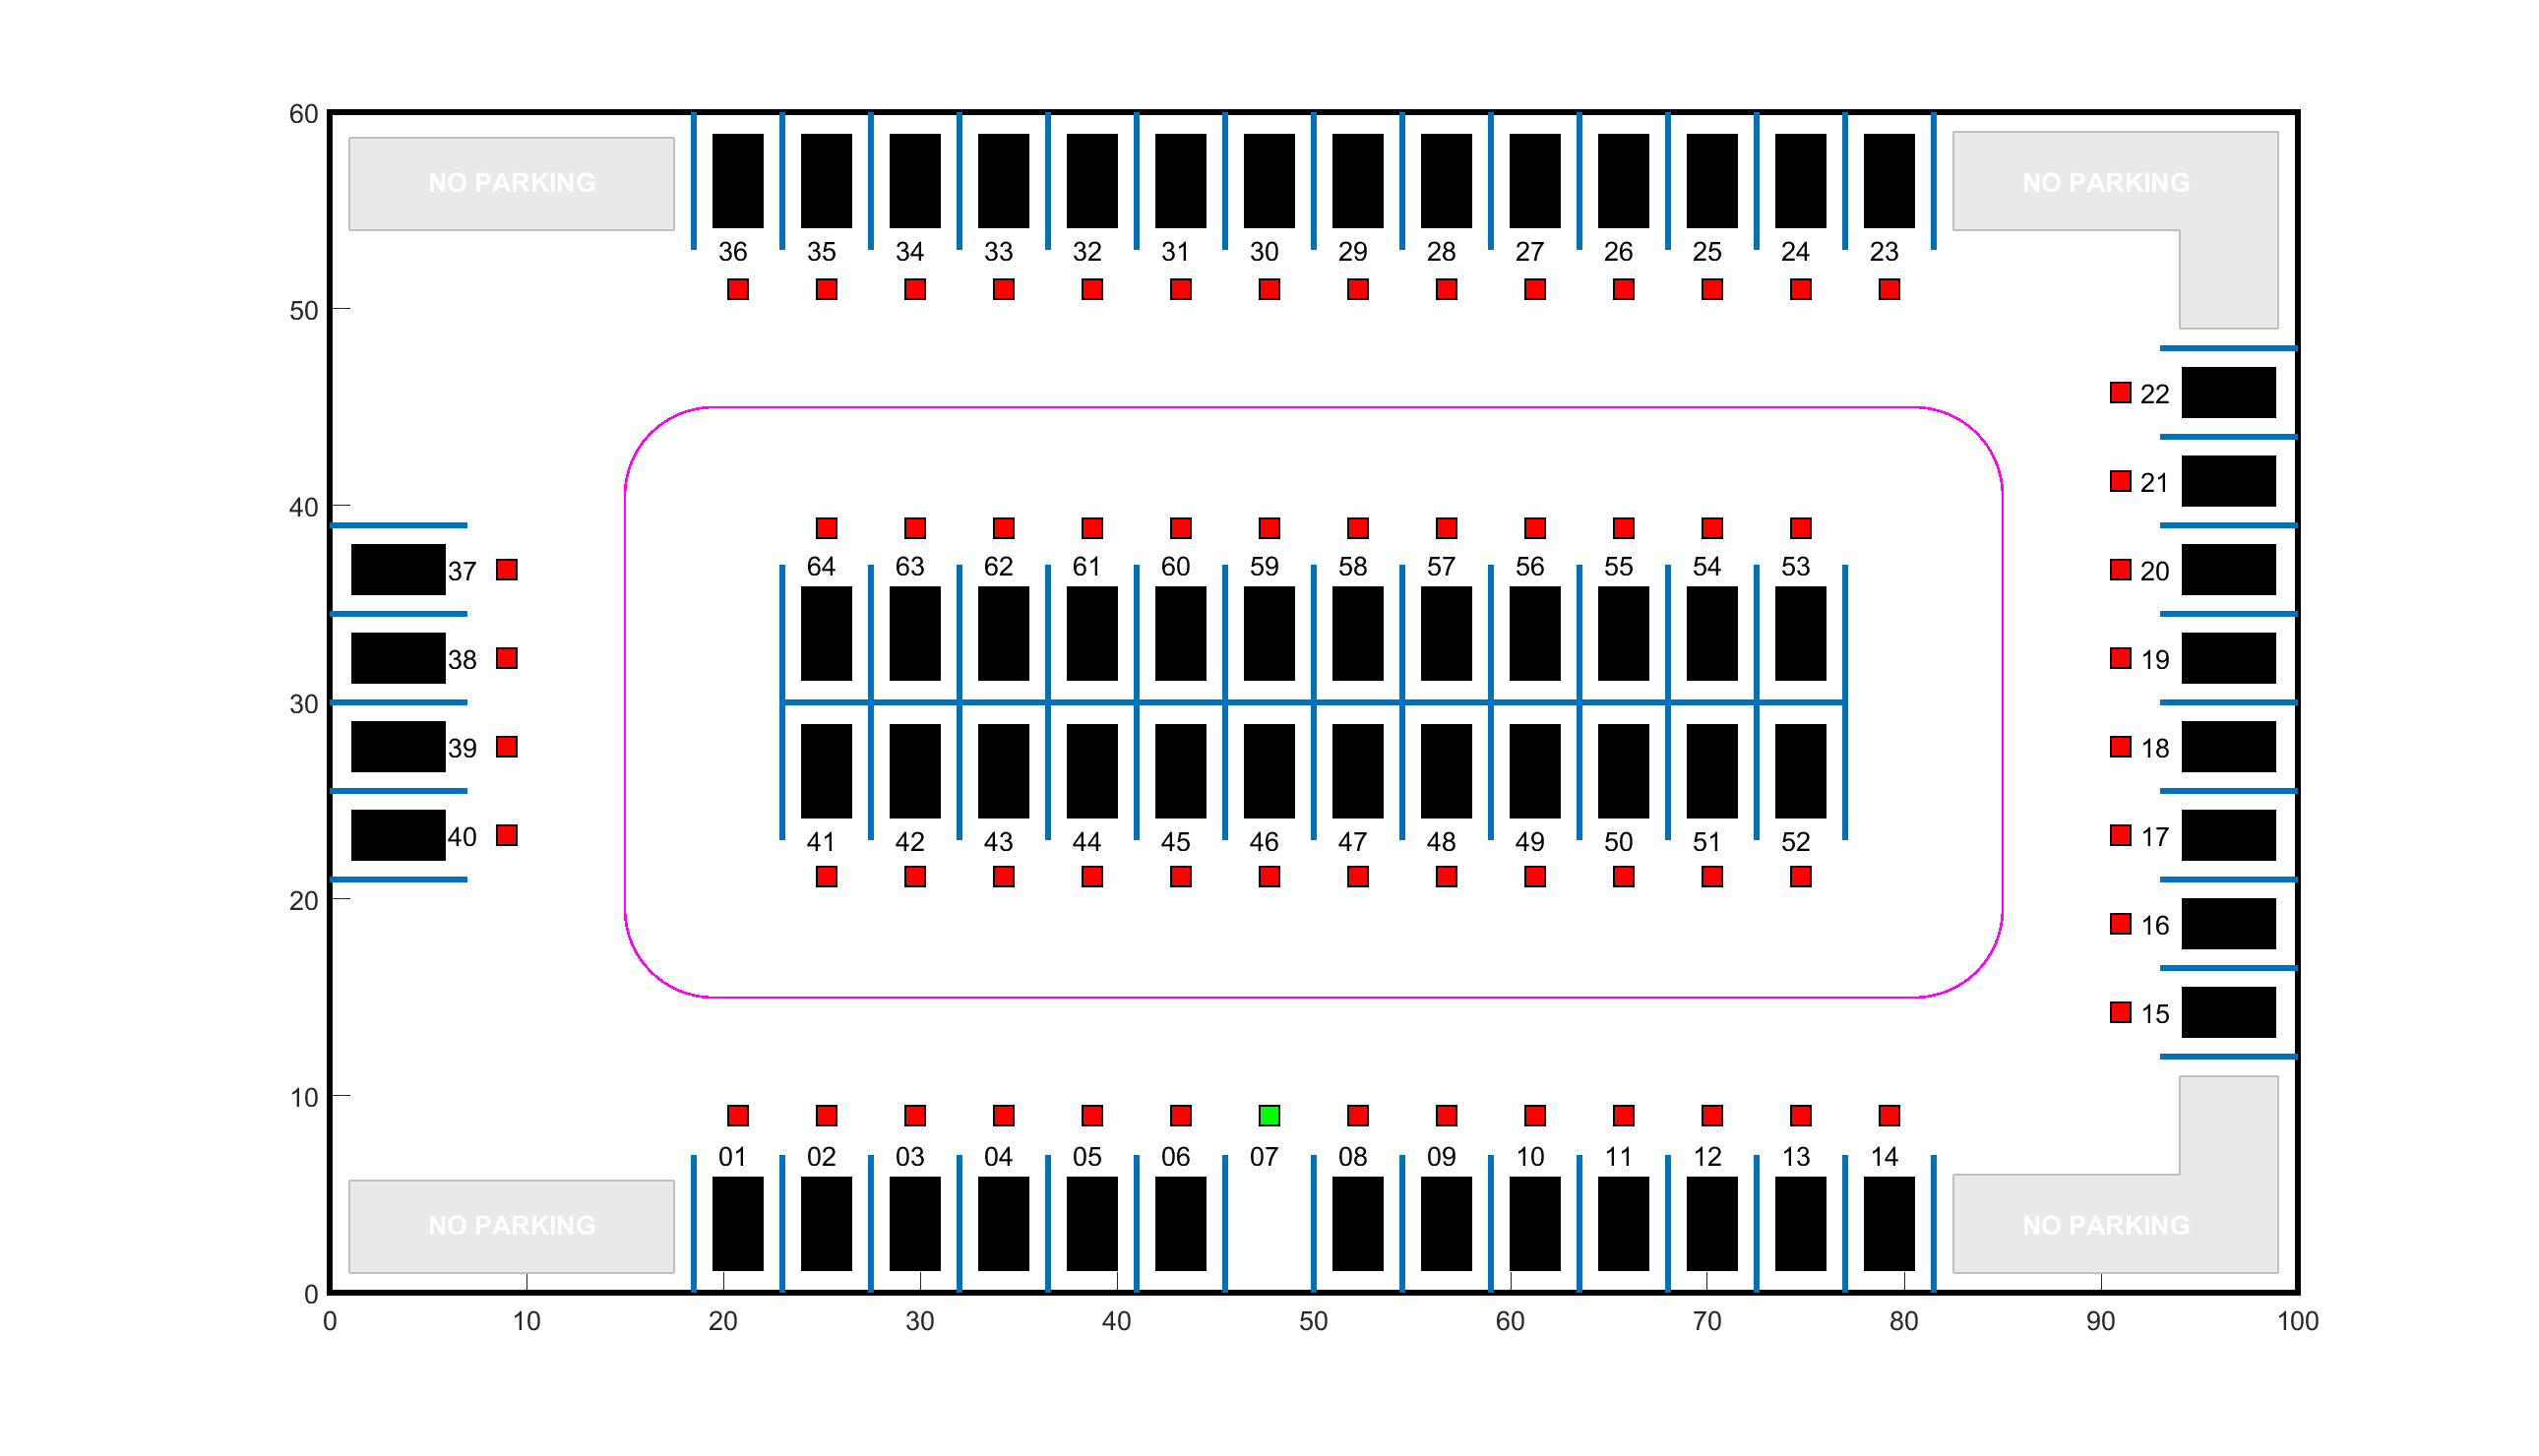

freeSpotIdx = 7;
map = ParkingLot(freeSpotIdx);


egoInitialPose = [20, 15, 0];
egoTargetPose = createTargetPose(map,freeSpotIdx)

egoTargetPose =    47.7500    4.9000   -1.5708



autoParkingValetParams
mdl = "rlAutoParkingValet";
open_system(mdl)

createMPCForParking

numObservations = 16;
obsInfo = rlNumericSpec([numObservations 1]);
obsInfo.Name = "observations";

steerMax = pi/4;
discreteSteerAngles = -steerMax : deg2rad(15) : steerMax;
actInfo = rlFiniteSetSpec(num2cell(discreteSteerAngles));
actInfo.Name = "actions";
numActions = numel(actInfo.Elements);

blk = mdl + "/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

env.ResetFcn = @autoParkingValetResetFcn;

rng(0)

criticNet = [
    featureInputLayer(numObservations)
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(1)
    ];

criticNet = dlnetwork(criticNet);
summary(criticNet)

   Initialized: true

   Number of learnables: 173k

   Inputs:
      1   'input'   16 features




critic = rlValueFunction(criticNet,obsInfo);

actorNet = [
    featureInputLayer(numObservations)
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(numActions)
    softmaxLayer
    ];

actorNet = dlnetwork(actorNet);
summary(actorNet)

   Initialized: true

   Number of learnables: 141.8k

   Inputs:
      1   'input'   16 features



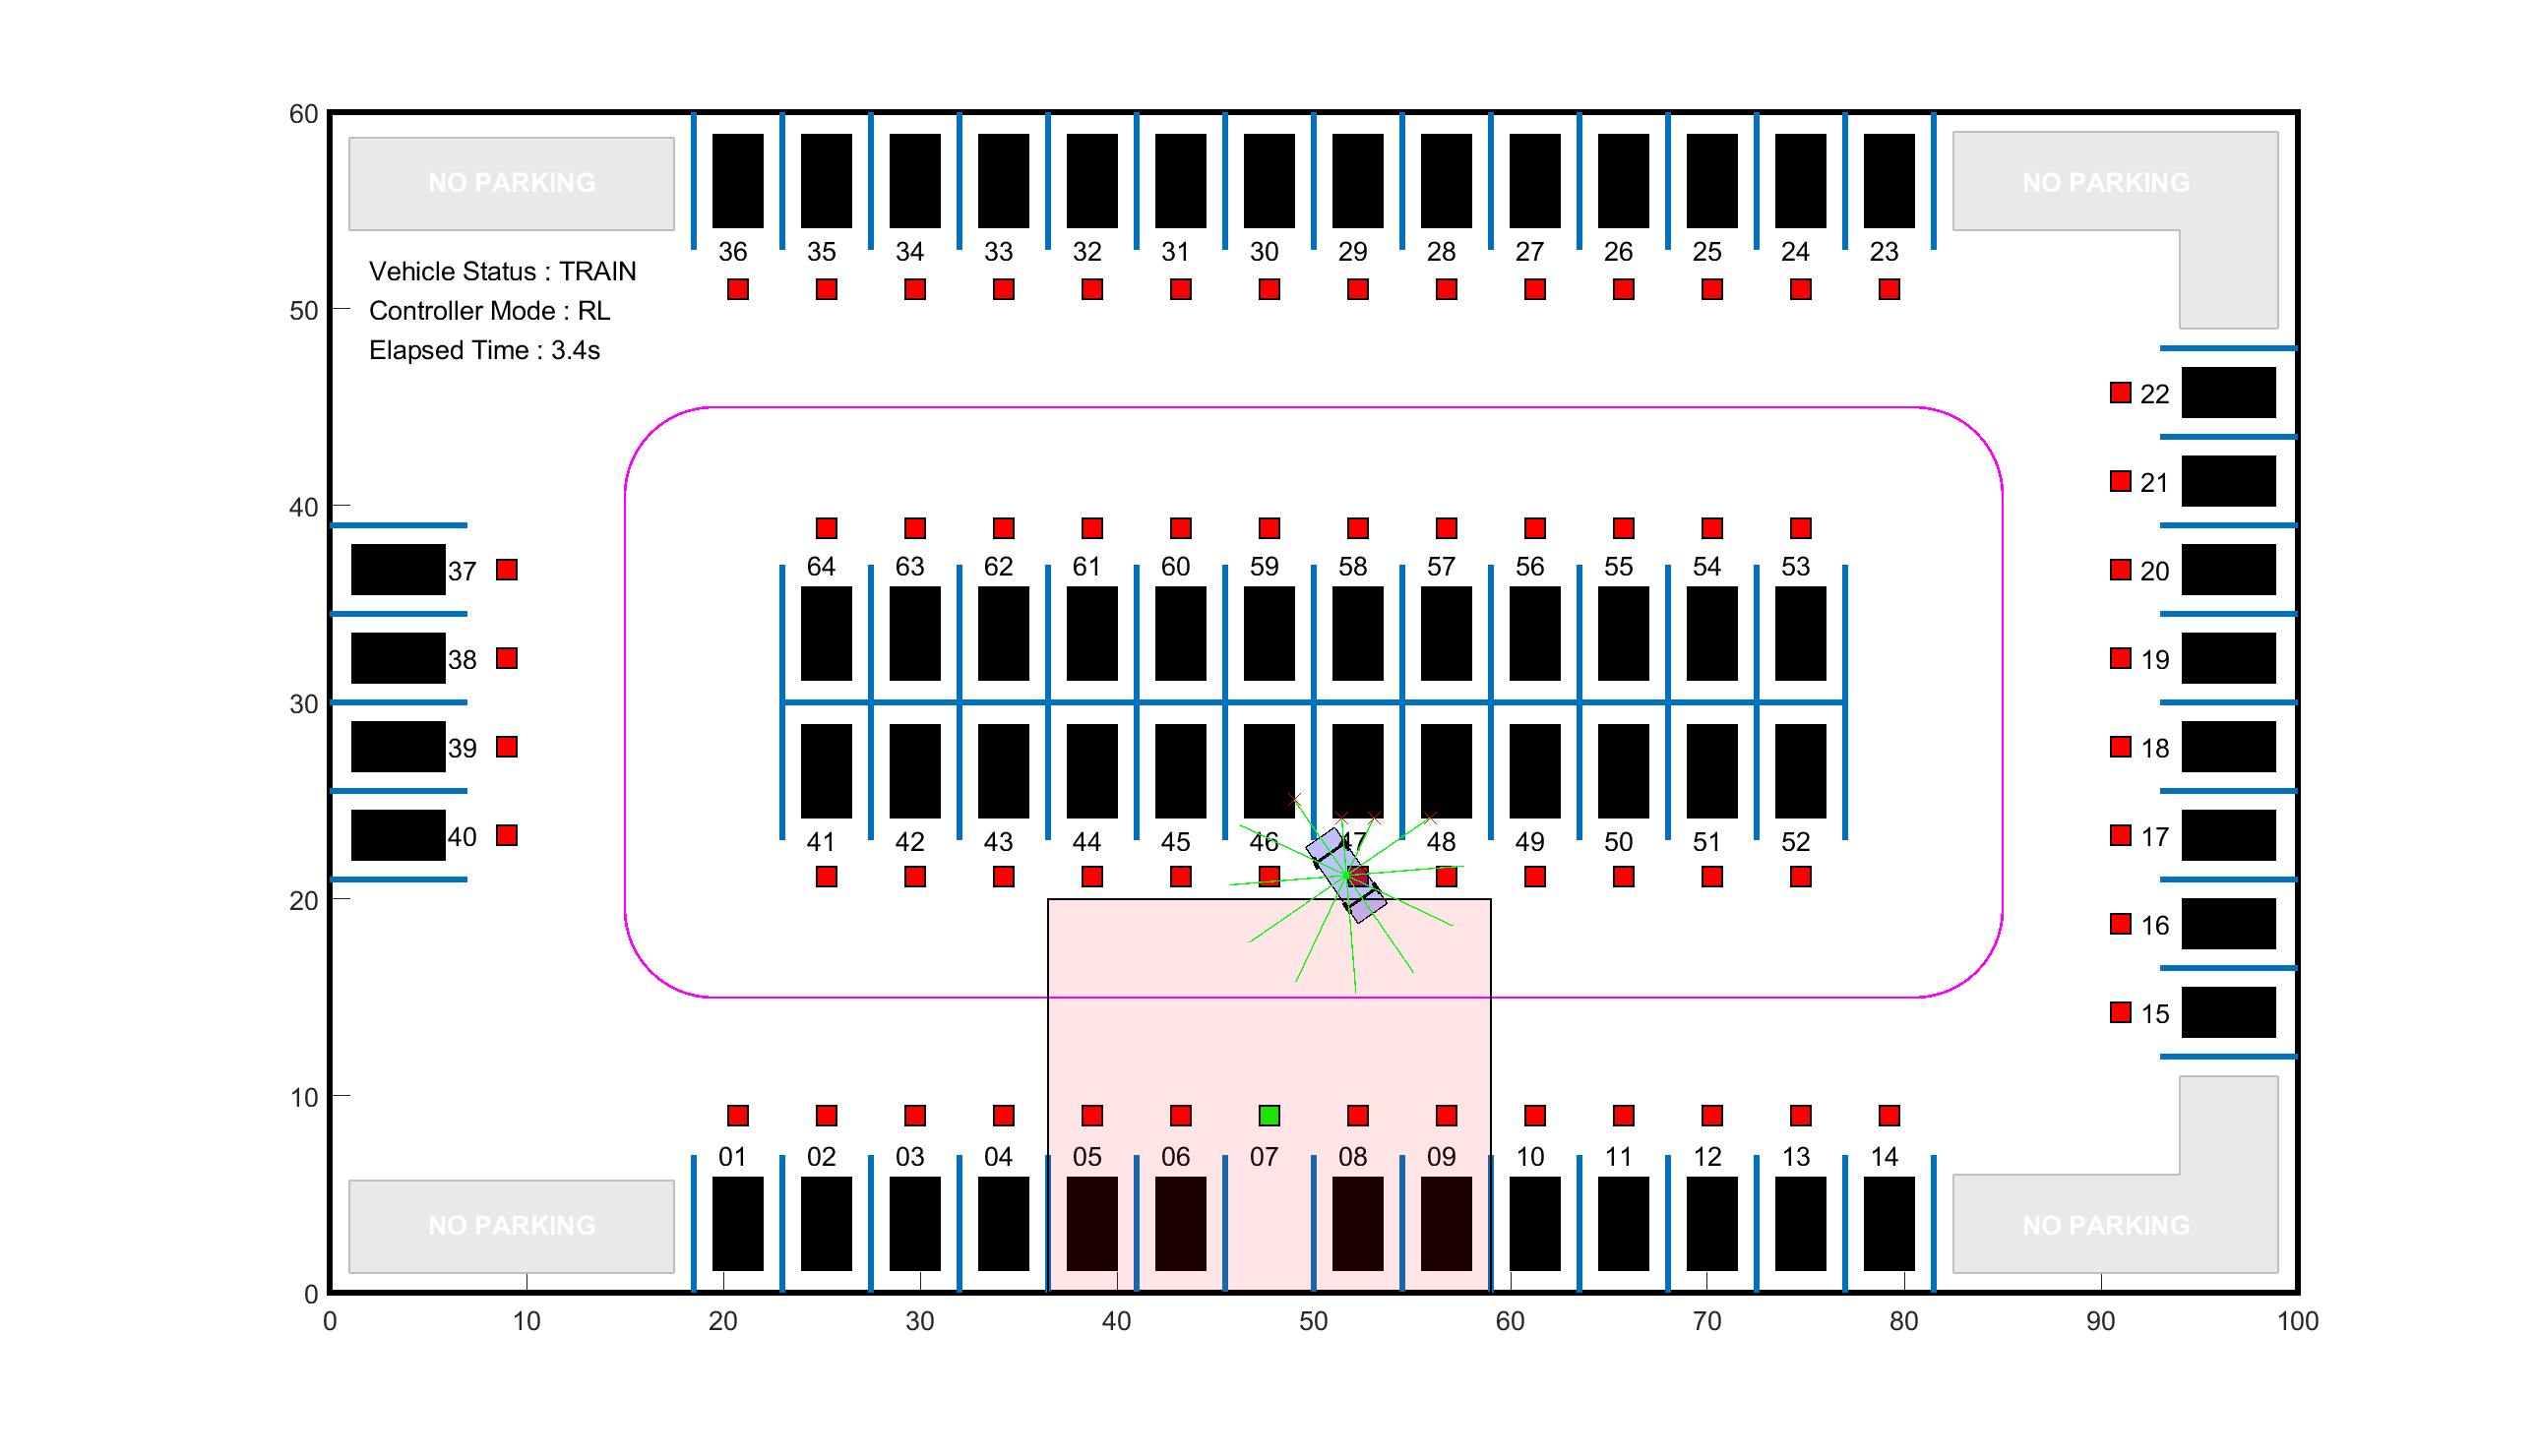


actor = rlDiscreteCategoricalActor(actorNet,obsInfo,actInfo);

criticOptions = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);
actorOptions = rlOptimizerOptions( ...
    LearnRate=2e-4, ...
    GradientThreshold=1);

agentOpts = rlPPOAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceHorizon=200,...
    ClipFactor=0.2,... 
    EntropyLossWeight=0.01,...
    MiniBatchSize=64,...
    NumEpoch=3,...
    AdvantageEstimateMethod="gae",...
    GAEFactor=0.94,...
    DiscountFactor=0.998);

agent = rlPPOAgent(actor,critic,agentOpts);

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000,...
    MaxStepsPerEpisode=200,...
    ScoreAveragingWindowLength=200,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=3000);

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
    save("TrainingResult.mat","agent")
else
    load('rlAutoParkingValetAgent.mat','agent');
end

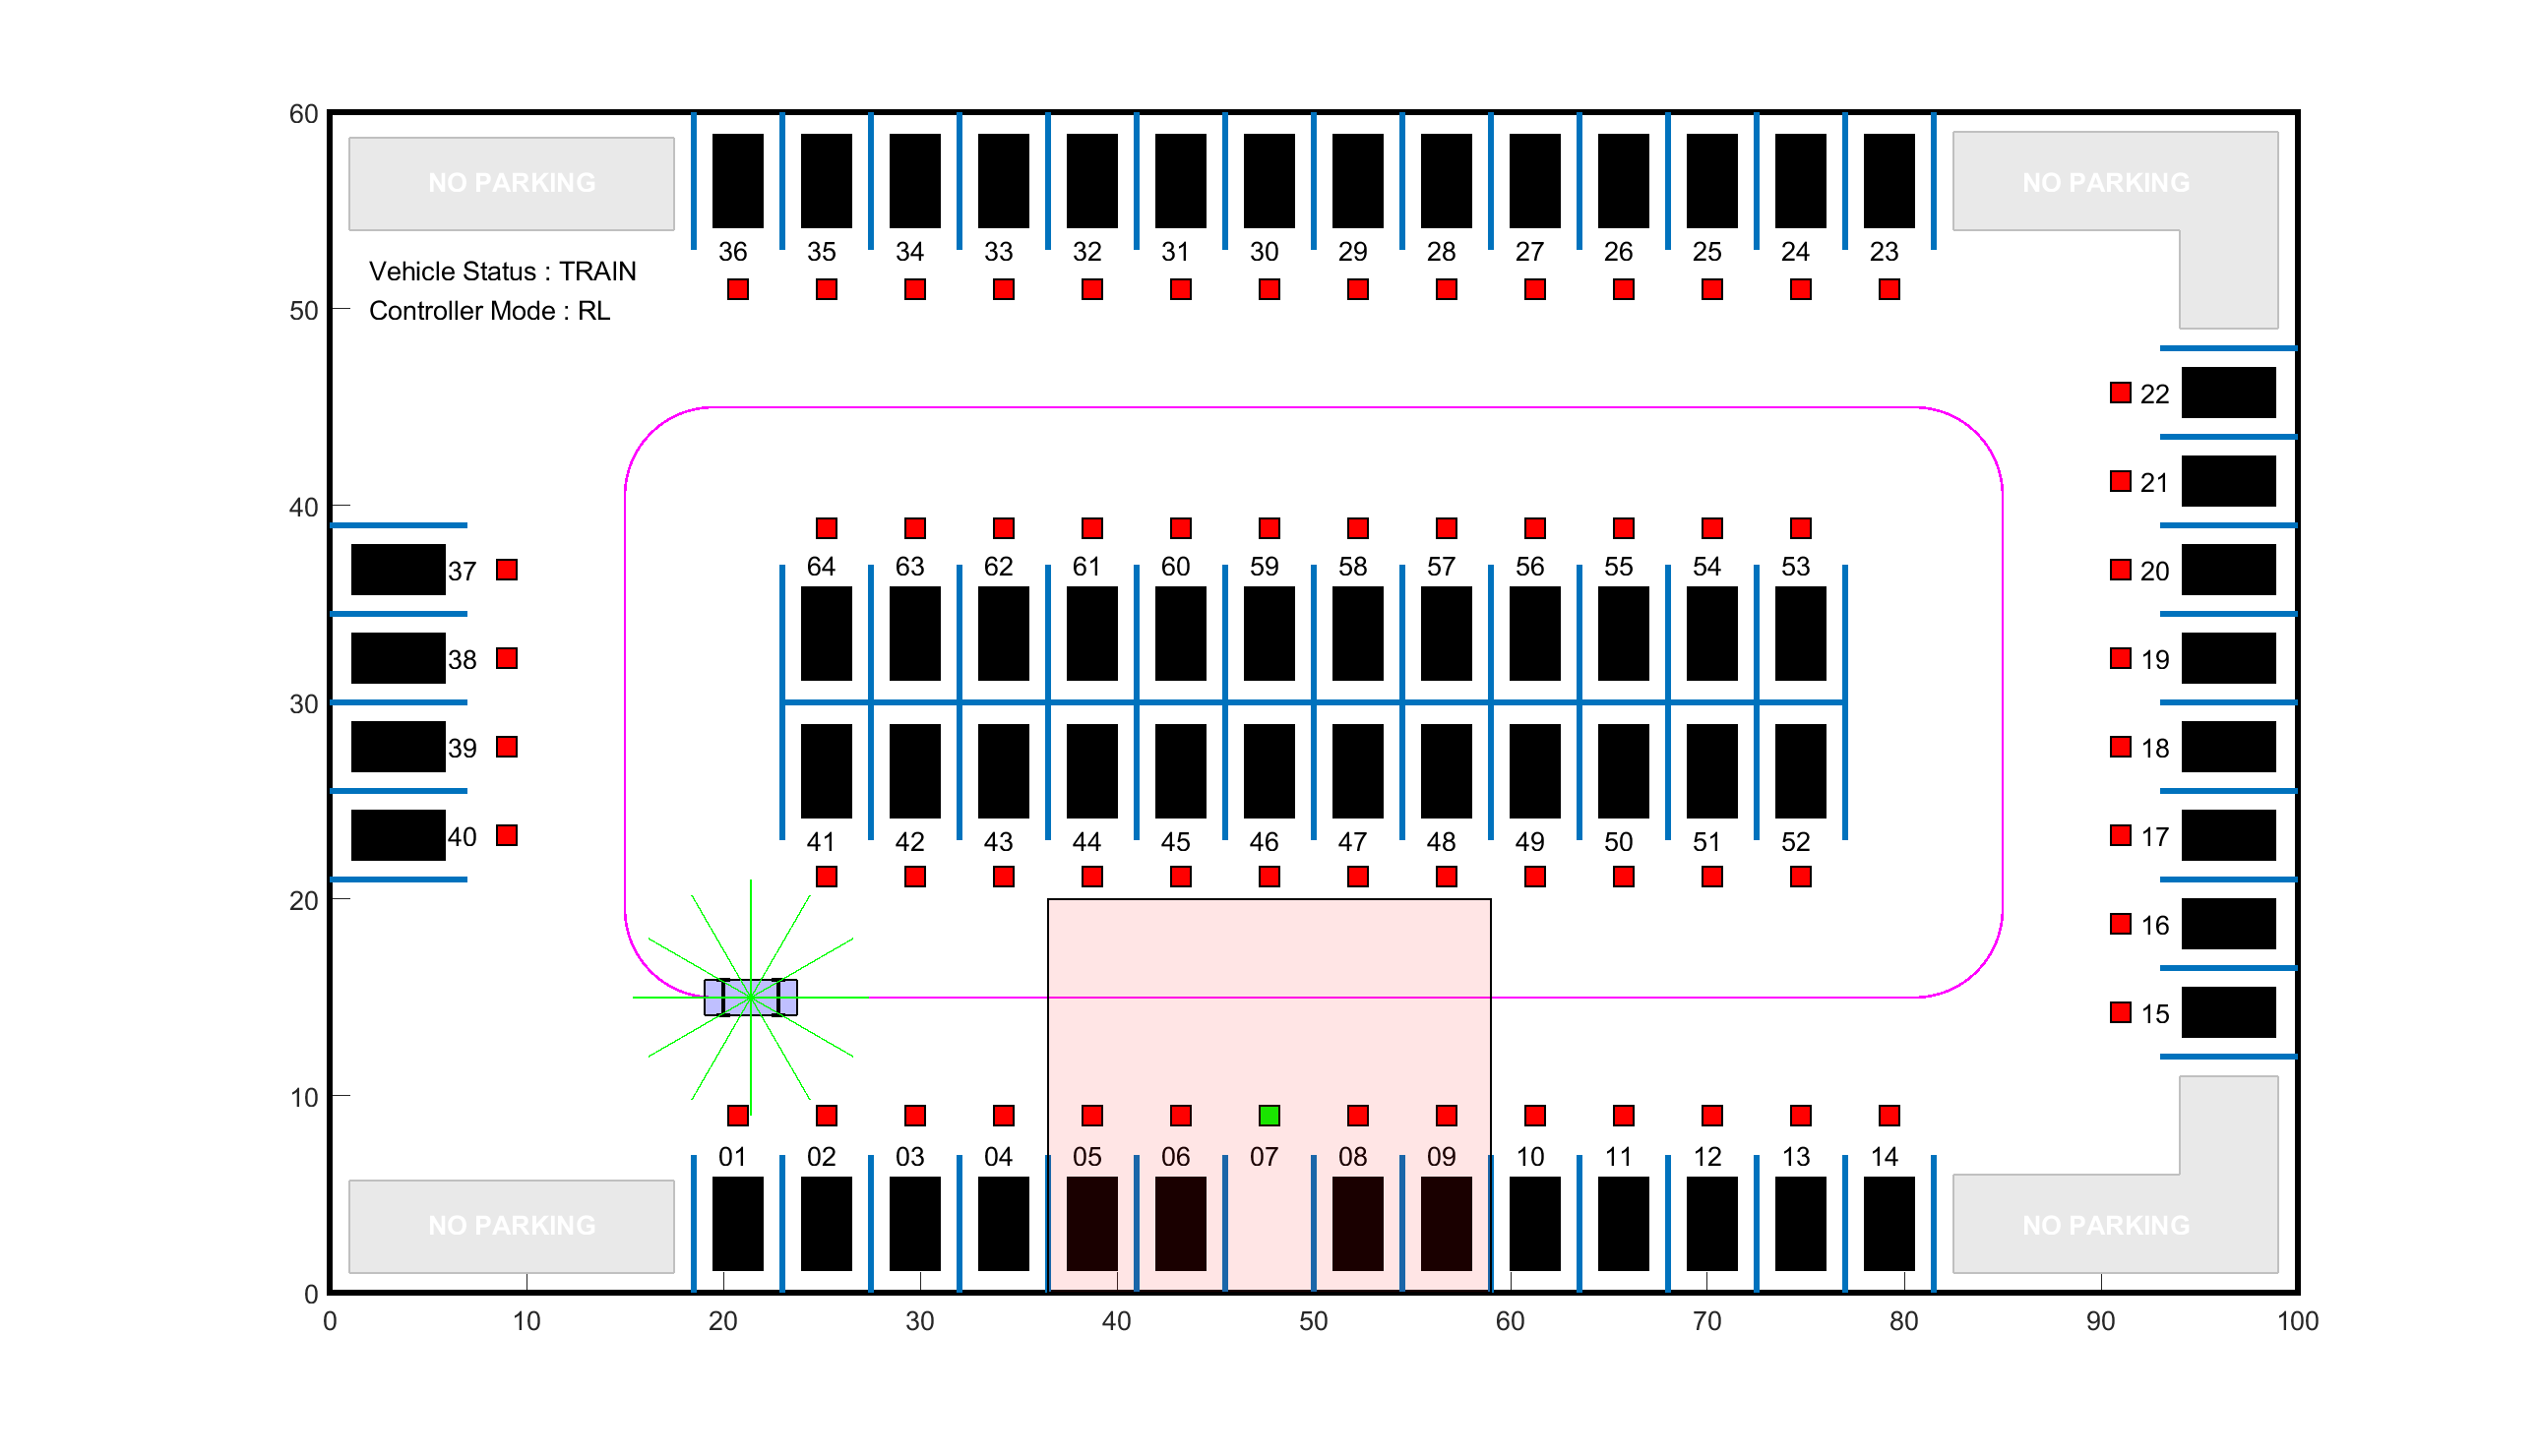

ans =   Simulink.SimulationOutput:

                   tout: [1x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



sim(mdl)


% Simpan hasil training: Episode, Episode Reward, Average Reward, dan Q0
numEpisodes = numel(trainingStats.EpisodeIndex);  % Ambil jumlah episode
episodeReward = trainingStats.EpisodeReward;      % Episode reward
averageReward = trainingStats.AverageReward;      % Average reward
episodeQ0 = trainingStats.EpisodeQ0;              % Q0 di setiap episode
step1 = trainingStats.EpisodeSteps;
step2 = trainingStats.TotalAgentSteps;

% Buat tabel untuk menyimpan data
rewardTable = table((1:numEpisodes)', episodeReward(:), averageReward(:), episodeQ0(:), step1(:), step2(:),...
                    'VariableNames', {'Episode', 'EpisodeReward', 'AverageReward', 'EpisodeQ0', 'EpisodeSteps', 'TotalAgentSteps'});

% Simpan ke file Excel
writetable(rewardTable, 'TrainingResultsPPOCombined.xlsx');

% Tampilkan tabel di Command Window
disp('Reward Table:');

Reward Table:


disp(rewardTable);

    Episode    EpisodeReward    AverageReward    EpisodeQ0     EpisodeSteps    TotalAgentSteps
    _______    _____________    _____________    __________    ____________    _______________

        1          -51.627          -51.627         -3.2694        112                  112   
        2          -50.935          -51.281         -6.0822         57                  169   
        3           -50.18          -50.914         -14.113        113                  282   
        4          -50.577           -50.83         -20.086         40                  322   
        5          -50.812          -50.826           -27.7         46                  368   
        6          -49.135          -50.544          -35.33        113                  481   
        7          -50.417         